Lab2 第一題

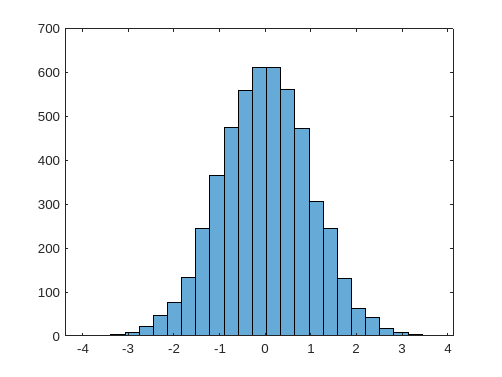

X1 = randn(5000, 1);
histogram(X1,25);

%The Sum of classes would change.
%The y-axix average will decrease.

Lab2 第二題

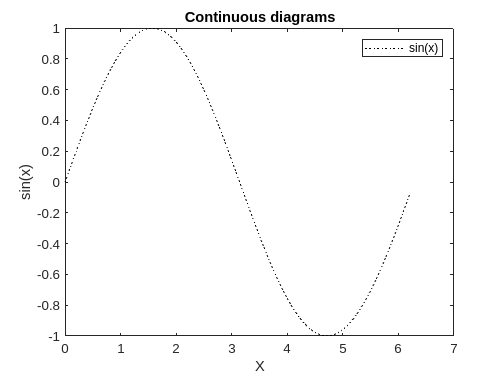

X2 = [0:0.1:2*pi];
Y2 = sin(X2);
plot(X2, Y2, 'k:')
title('Continuous diagrams')
xlabel('X')
ylabel('sin(x)')
legend('sin(x)')

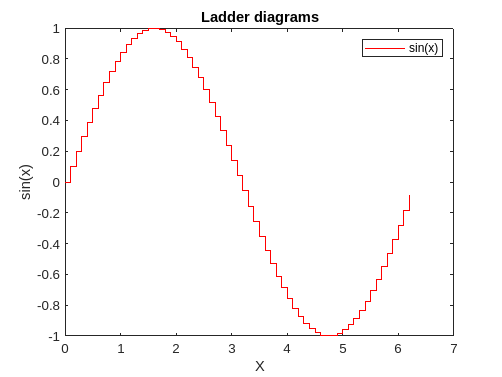

stairs(X2, Y2, 'r-')
title('Ladder diagrams')
xlabel('X')
ylabel('sin(x)')
legend('sin(x)')

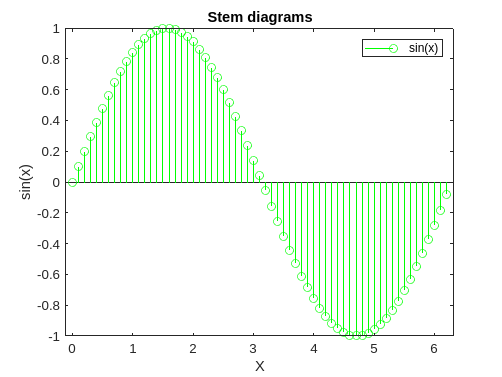

stem(X2, Y2, 'go-')
title('Stem diagrams')
xlabel('X')
ylabel('sin(x)')
legend('sin(x)')

Lab2 第三題

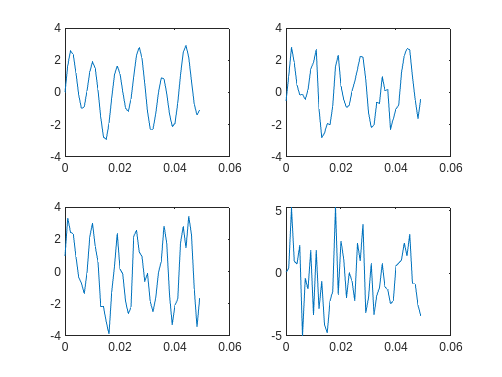

figure;
t = (0:0.001:1)';
a = 1; b = 2;
y = a*sin(2*pi*50*t)+b*sin(2*pi*120*t);
subplot(221);
yn1 = y+0*randn(size(t));
plot(t(1:50), yn1(1:50));
subplot(222);
yn2 = y+0.5*randn(size(t));
plot(t(1:50), yn2(1:50));
subplot(223);
yn3 = y+1*randn(size(t));
plot(t(1:50), yn3(1:50));
subplot(224);
yn4 = y+2*randn(size(t));
plot(t(1:50), yn4(1:50));

Lab2 第四題

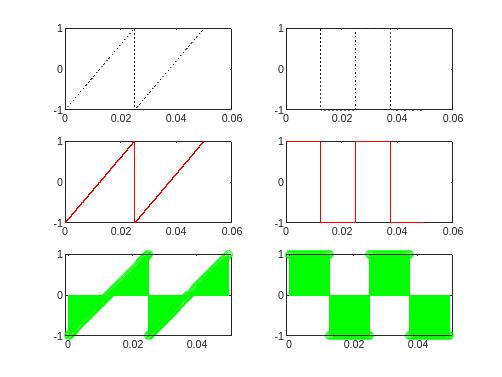

figure;
fs = 10000;
t4 = 0:1/fs:2;
y41 = sawtooth(2*pi*40*t4);
y42 = square(2*pi*40*t4);
subplot(321);
plot(t4(1:500), y41(1:500), 'k:');
subplot(322);
plot(t4(1:500), y42(1:500), 'k:');
subplot(323);
stairs(t4(1:500), y41(1:500), 'r-');
subplot(324);
stairs(t4(1:500), y42(1:500), 'r-');
subplot(325);
stem(t4(1:500), y41(1:500), 'go-');
subplot(326);
stem(t4(1:500), y42(1:500), 'go-');

Lab2 第五題

X51 = importdata('data1.txt');
X52 = importdata('data2.txt');
p_data1 = fopen('p_data1.txt', 'w');
p_data1 = (X51)*2

p_data1 =     0.0315   -0.0002
    0.0631   -0.0000
    0.0946    0.0003
    0.1261   -0.0000
    0.1577    0.0001
    0.1892    0.0000
    0.2208    0.0001
    0.2523    0.0004
    0.2838    0.0021
    0.3154    0.0019


save('p_data1.txt', "p_data1", "-ascii");

d2_header = X52.textdata;
d2_num = X52.data * 2;
p_data2 = fopen('p_data2.txt', 'w');
for i = 1:length(d2_header)
    fprintf(p_data2, '%s\n', d2_header{i});
end
for i = 1:length(d2_num) 
    fprintf(p_data2, '%g\n', d2_num(i));
end
p_data2 = importdata('p_data2.txt')

p_data2 = struct with fields:
          data: [6×1 double]
      textdata: {2×1 cell}
    colheaders: {'---Head2'}


Lab2 第六題

A6 = [1, 0, 1, 0, 1, 0, 1, 0, 1, 0, 1, 1, 0, 0, 0, 1, 1, 0, 0, 1];
A6 = reshape(A6, [5,4]);
A6 = A6'

A6 =      1     0     1     0     1
     0     1     0     1     0
     1     1     0     0     0
     1     1     0     0     1


B6 = [mean(A6(1,:)), mean(A6(2,:)), mean(A6(3,:)), mean(A6(4,:))];
C6 = [round(B6(1)), round(B6(2)), round(B6(3)), round(B6(4))];
A6 = [C6' A6]

A6 =      1     1     0     1     0     1
     0     0     1     0     1     0
     0     1     1     0     0     0
     1     1     1     0     0     1
